# Data to use for aggregation, WSN Mini-project

close all, clear, clc;
%source1_data = randi([15,30],100,1)';
%source2_data = randi([18,25],100,1)';
%source3_data = randi([12,21],100,1)';
%source4_data = randi([8,16],100,1)';
load('test.mat')

time = 1:1:length(source1_data);


save('test.mat', "source1_data", "source2_data", "source3_data", "source4_data")

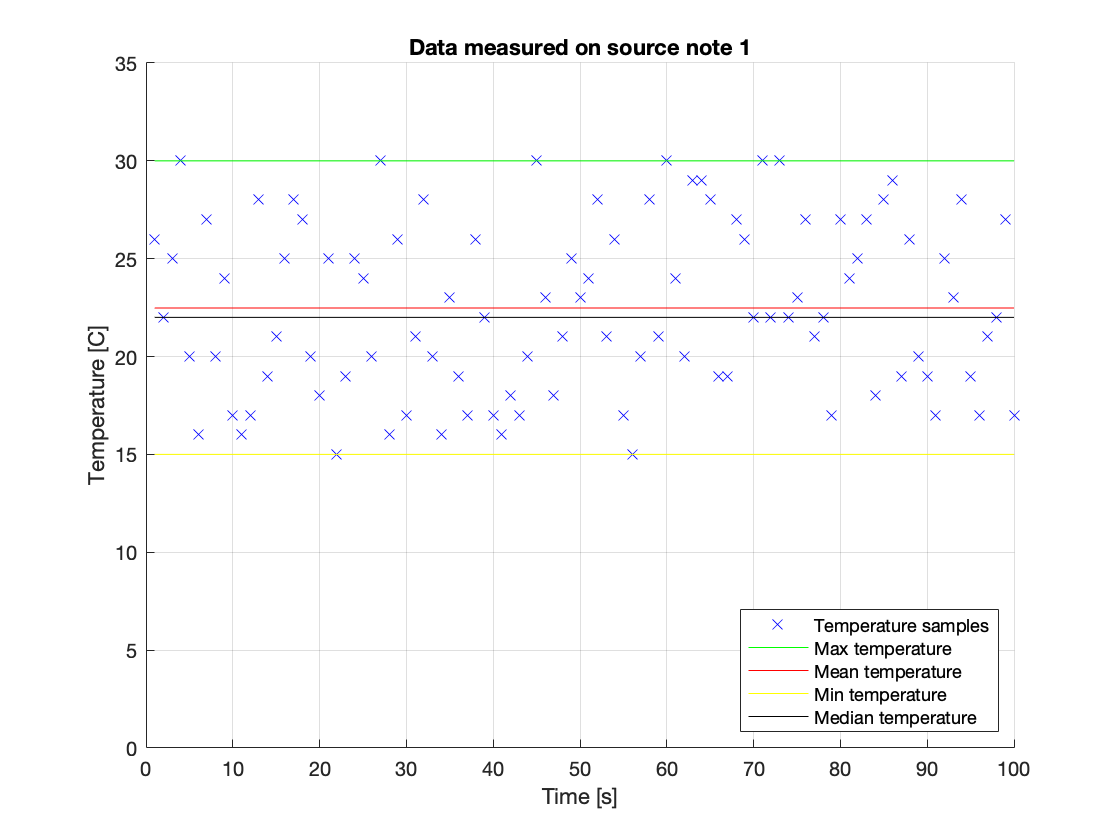


close all
s1_data = source1_data;
% Calculate mean, min, max and median of sensored data
source1_mean = mean(s1_data);
source1_min = min(s1_data);
source1_max = max(s1_data);
source1_median = median(s1_data);
source1_samples = length(s1_data);

% Plot the sampled and aggregated data
figure(1)
scatter(time, s1_data, 'x', 'b')
ylim([0;max(s1_data)+5]), grid
title('Data measured on source note 1')
xlabel('Time [s]'), ylabel('Temperature [C]')
hold on
plot(time, source1_max*ones(size(time)), 'g')
plot(time, source1_mean*ones(size(time)), 'r')
plot(time, source1_min*ones(size(time)),'y')
plot(time, source1_median*ones(size(time)),'k')
legend('Temperature samples', 'Max temperature', 'Mean temperature', 'Min temperature', 'Median temperature', location='southeast')

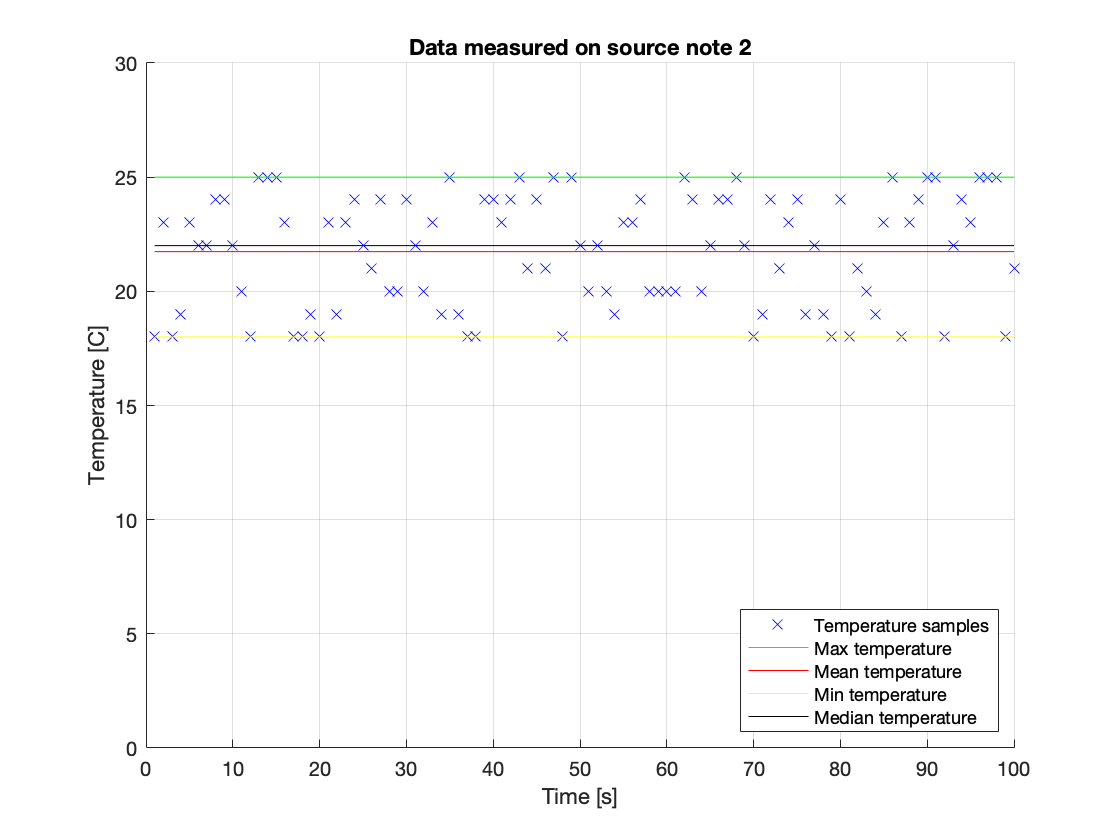

close all
s2_data = source2_data;
% Calculate mean, min, max and median of sensored data
source2_mean = mean(s2_data);
source2_min = min(s2_data);
source2_max = max(s2_data);
source2_median = median(s2_data);
source2_samples = length(s2_data);

% Plot the aggregated data
figure(2)
scatter(time, s2_data, 'x', 'b')
ylim([0;max(s2_data)+5]), grid
title('Data measured on source note 2')
xlabel('Time [s]'), ylabel('Temperature [C]')
hold on
plot(time, source2_max*ones(size(time)), 'g')
plot(time, source2_mean*ones(size(time)), 'r')
plot(time, source2_min*ones(size(time)),'y')
plot(time, source2_median*ones(size(time)),'k')
legend('Temperature samples', 'Max temperature', 'Mean temperature', 'Min temperature', 'Median temperature', location='southeast')

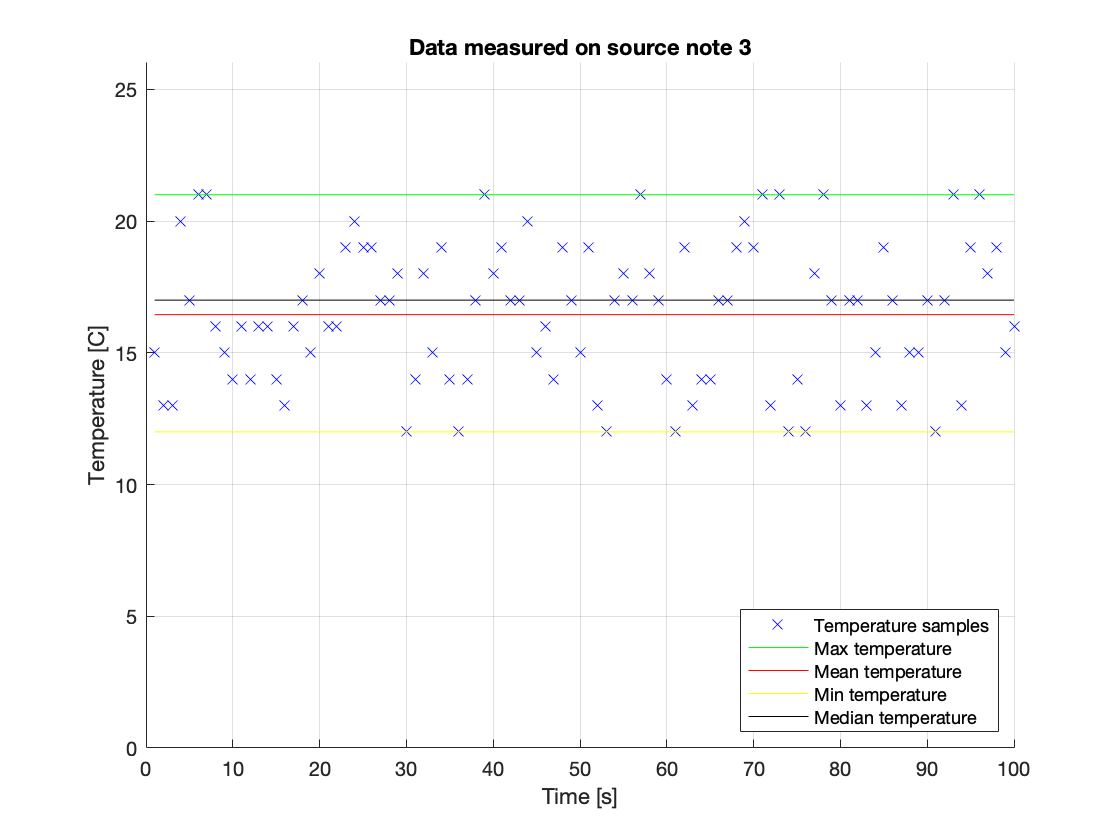

close all
s3_data = source3_data;
% Calculate mean, min, max and median of sensored data
source3_mean = mean(s3_data);
source3_min = min(s3_data);
source3_max = max(s3_data);
source3_median = median(s3_data);
source3_samples = length(s3_data);

% Plot the sampled and aggregated data
figure(3)
scatter(time, s3_data, 'x', 'b')
ylim([0;max(s3_data)+5]), grid
title('Data measured on source note 3')
xlabel('Time [s]'), ylabel('Temperature [C]')
hold on
plot(time, source3_max*ones(size(time)), 'g')
plot(time, source3_mean*ones(size(time)), 'r')
plot(time, source3_min*ones(size(time)),'y')
plot(time, source3_median*ones(size(time)),'k')
legend('Temperature samples', 'Max temperature', 'Mean temperature', 'Min temperature', 'Median temperature', location='southeast')

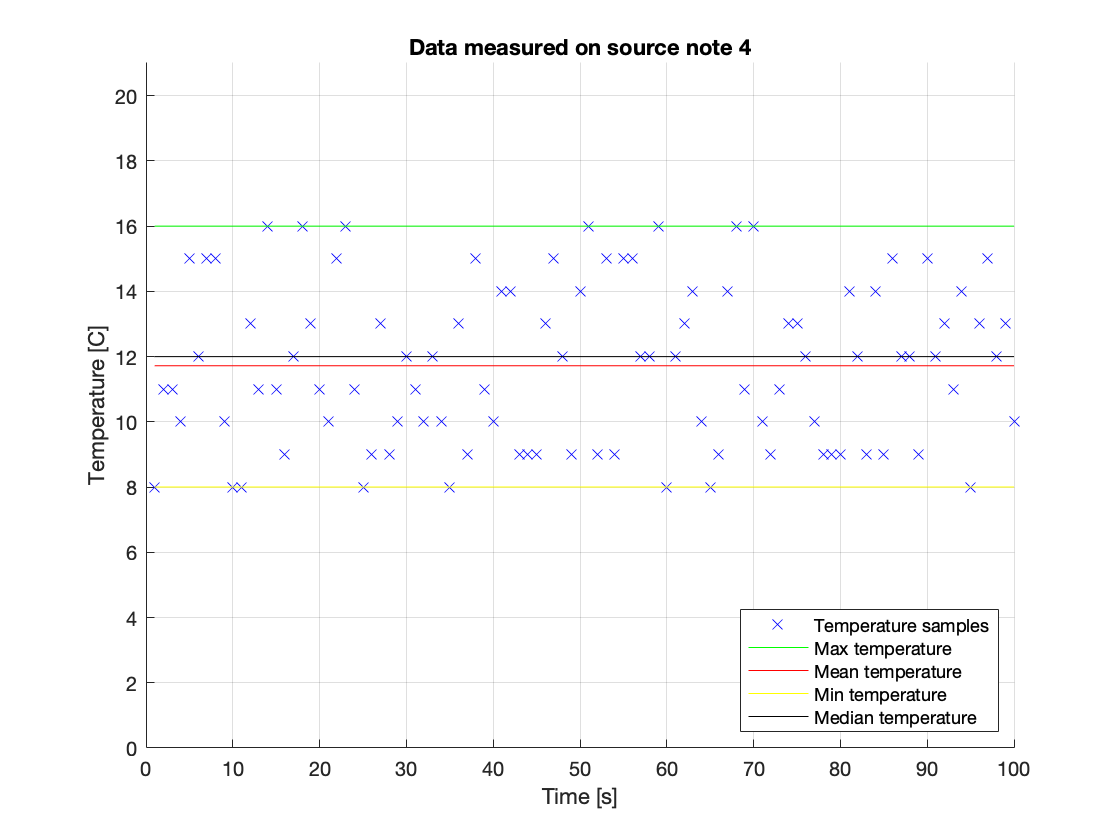

close all
s4_data = source4_data;
% Calculate mean, min, max and median of sensored data
source4_mean = mean(s4_data);
source4_min = min(s4_data);
source4_max = max(s4_data);
source4_median = median(s4_data);
source4_samples = length(s4_data);

% Plot the sampled and aggregated data
figure(4)
scatter(time, s4_data, 'x', 'b')
ylim([0;max(s4_data)+5]), grid
title('Data measured on source note 4')
xlabel('Time [s]'), ylabel('Temperature [C]')
hold on
plot(time, source4_max*ones(size(time)), 'g')
plot(time, source4_mean*ones(size(time)), 'r')
plot(time, source4_min*ones(size(time)),'y')
plot(time, source4_median*ones(size(time)),'k')
legend('Temperature samples', 'Max temperature', 'Mean temperature', 'Min temperature', 'Median temperature', location='southeast')

x = cat(1,s1_data',s2_data', s3_data', s4_data')';
%global_mean = (s1_data+s2_data+s3_data+s4_data)/400
global_mean = mean(x)

global_mean = 18.0975

global_min = min(x)

global_min = 8

global_max = max(x)

global_max = 30

global_median = median(x)

global_median = 18

%global_median = median([source1_median, source2_median, source3_median, source4_median ])

%% Calculate mean for aggregation mote 1 
agg11 = zeros(1,10);
agg12 = zeros(1,10);
agg13 = zeros(1,10);
agg14 = zeros(1,10);
agg15 = zeros(1,10);
agg16 = zeros(1,10);
agg17 = zeros(1,10);
agg18 = zeros(1,10);
agg19 = zeros(1,10);
agg10 = zeros(1,10);

for i=1:length(s1_data)
    if i <= 10
        agg11(i) = s1_data(i);
    end
    if i > 10 && i <=20
        agg12(i-10) = s1_data(i);
    end
    if i > 20 && i <=30  
        agg13(i-20) = s1_data(i);
    end
    if i > 30 && i <=40  
        agg14(i-30) = s1_data(i);
    end
    if i > 40 && i <=50  
        agg15(i-40) = s1_data(i);
    end
    if i > 50 && i <=60  
        agg16(i-50) = s1_data(i);
    end
    if i > 60 && i <=70  
        agg17(i-60) = s1_data(i);
    end
    if i > 70 && i <=80  
        agg18(i-70) = s1_data(i);
    end
    if i > 80 && i <=90  
        agg19(i-80) = s1_data(i);
    end
    if i > 90 && i <=100  
        agg10(i-90) = s1_data(i);
    end
end

% Mean
mean_agg11 = mean(agg11);
mean_agg12 = mean(agg12);
mean_agg13 = mean(agg13);
mean_agg14 = mean(agg14);
mean_agg15 = mean(agg15);
mean_agg16 = mean(agg16);
mean_agg17 = mean(agg17);
mean_agg18 = mean(agg18);
mean_agg19 = mean(agg19);
mean_agg10 = mean(agg10);
% Max
max_agg11 = max(agg11);
max_agg12 = max(agg12);
max_agg13 = max(agg13);
max_agg14 = max(agg14);
max_agg15 = max(agg15);
max_agg16 = max(agg16);
max_agg17 = max(agg17);
max_agg18 = max(agg18);
max_agg19 = max(agg19);
max_agg10 = max(agg10);
% Min
min_agg11 = min(agg11);
min_agg12 = min(agg12);
min_agg13 = min(agg13);
min_agg14 = min(agg14);
min_agg15 = min(agg15);
min_agg16 = min(agg16);
min_agg17 = min(agg17);
min_agg18 = min(agg18);
min_agg19 = min(agg19);
min_agg10 = min(agg10);
% Median
median_agg11 =  median(agg11);
median_agg12 =  median(agg12);
median_agg13 =  median(agg13);
median_agg14 =  median(agg14);
median_agg15 =  median(agg15);
median_agg16 =  median(agg16);
median_agg17 =  median(agg17);
median_agg18 =  median(agg18);
median_agg19 =  median(agg19);
median_agg10 =  median(agg10);

%% calculate mean for aggregation mote 2
agg21 = zeros(1,10);
agg22 = zeros(1,10);
agg23 = zeros(1,10);
agg24 = zeros(1,10);
agg25 = zeros(1,10);
agg26 = zeros(1,10);
agg27 = zeros(1,10);
agg28 = zeros(1,10);
agg29 = zeros(1,10);
agg20 = zeros(1,10);

for i=1:length(s2_data)
    if i <= 10
        agg21(i) = s2_data(i);
    end
    if i > 10 && i <=20
        agg22(i-10) = s2_data(i);
    end
    if i > 20 && i <=30  
        agg23(i-20) = s2_data(i);
    end
    if i > 30 && i <=40  
        agg24(i-30) = s2_data(i);
    end
    if i > 40 && i <=50  
        agg25(i-40) = s2_data(i);
    end
    if i > 50 && i <=60  
        agg26(i-50) = s2_data(i);
    end
    if i > 60 && i <=70  
        agg27(i-60) = s2_data(i);
    end
    if i > 70 && i <=80  
        agg28(i-70) = s2_data(i);
    end
    if i > 80 && i <=90  
        agg29(i-80) = s2_data(i);
    end
    if i > 90 && i <=100  
        agg20(i-90) = s2_data(i);
    end
end
% Mean
mean_agg21 = mean(agg21);
mean_agg22 = mean(agg22);
mean_agg23 = mean(agg23);
mean_agg24 = mean(agg24);
mean_agg25 = mean(agg25);
mean_agg26 = mean(agg26);
mean_agg27 = mean(agg27);
mean_agg28 = mean(agg28);
mean_agg29 = mean(agg29);
mean_agg20 = mean(agg20);
% Max
max_agg21 = max(agg21);
max_agg22 = max(agg22);
max_agg23 = max(agg23);
max_agg24 = max(agg24);
max_agg25 = max(agg25);
max_agg26 = max(agg26);
max_agg27 = max(agg27);
max_agg28 = max(agg28);
max_agg29 = max(agg29);
max_agg20 = max(agg20);
% Min
min_agg21 = min(agg21);
min_agg22 = min(agg22);
min_agg23 = min(agg23);
min_agg24 = min(agg24);
min_agg25 = min(agg25);
min_agg26 = min(agg26);
min_agg27 = min(agg27);
min_agg28 = min(agg28);
min_agg29 = min(agg29);
min_agg20 = min(agg20);
% Median
median_agg21 =  median(agg21);
median_agg22 =  median(agg22);
median_agg23 =  median(agg23);
median_agg24 =  median(agg24);
median_agg25 =  median(agg25);
median_agg26 =  median(agg26);
median_agg27 =  median(agg27);
median_agg28 =  median(agg28);
median_agg29 =  median(agg29);
median_agg20 =  median(agg20);

%% Calculate mean for aggregation mote 3
agg31 = zeros(1,10);
agg32 = zeros(1,10);
agg33 = zeros(1,10);
agg34 = zeros(1,10);
agg35 = zeros(1,10);
agg36 = zeros(1,10);
agg37 = zeros(1,10);
agg38 = zeros(1,10);
agg39 = zeros(1,10);
agg30 = zeros(1,10);

for i=1:length(s2_data)
    if i <= 10
        agg31(i) = s3_data(i);
    end
    if i > 10 && i <=20
        agg32(i-10) = s3_data(i);
    end
    if i > 20 && i <=30  
        agg33(i-20) = s3_data(i);
    end
    if i > 30 && i <=40  
        agg34(i-30) = s3_data(i);
    end
    if i > 40 && i <=50  
        agg35(i-40) = s3_data(i);
    end
    if i > 50 && i <=60  
        agg36(i-50) = s3_data(i);
    end
    if i > 60 && i <=70  
        agg37(i-60) = s3_data(i);
    end
    if i > 70 && i <=80  
        agg38(i-70) = s3_data(i);
    end
    if i > 80 && i <=90  
        agg39(i-80) = s3_data(i);
    end
    if i > 90 && i <=100  
        agg30(i-90) = s3_data(i);
    end
end

% Mean
mean_agg31 = mean(agg31);
mean_agg32 = mean(agg32);
mean_agg33 = mean(agg33);
mean_agg34 = mean(agg34);
mean_agg35 = mean(agg35);
mean_agg36 = mean(agg36);
mean_agg37 = mean(agg37);
mean_agg38 = mean(agg38);
mean_agg39 = mean(agg39);
mean_agg30 = mean(agg30);
% Max
max_agg31 = max(agg31);
max_agg32 = max(agg32);
max_agg33 = max(agg33);
max_agg34 = max(agg34);
max_agg35 = max(agg35);
max_agg36 = max(agg36);
max_agg37 = max(agg37);
max_agg38 = max(agg38);
max_agg39 = max(agg39);
max_agg30 = max(agg30);
% Min
min_agg31 = min(agg31);
min_agg32 = min(agg32);
min_agg33 = min(agg33);
min_agg34 = min(agg34);
min_agg35 = min(agg35);
min_agg36 = min(agg36);
min_agg37 = min(agg37);
min_agg38 = min(agg38);
min_agg39 = min(agg39);
min_agg30 = min(agg30);
% Median
median_agg31 =  median(agg31);
median_agg32 =  median(agg32);
median_agg33 =  median(agg33);
median_agg34 =  median(agg34);
median_agg35 =  median(agg35);
median_agg36 =  median(agg36);
median_agg37 =  median(agg37);
median_agg38 =  median(agg38);
median_agg39 =  median(agg39);
median_agg30 =  median(agg30);

%% Calculate mean for aggregation mote 4
agg41 = zeros(1,10);
agg42 = zeros(1,10);
agg43 = zeros(1,10);
agg44 = zeros(1,10);
agg45 = zeros(1,10);
agg46 = zeros(1,10);
agg47 = zeros(1,10);
agg48 = zeros(1,10);
agg49 = zeros(1,10);
agg40 = zeros(1,10);

for i=1:length(s4_data)
    if i <= 10
        agg41(i) = s4_data(i);
    end
    if i > 10 && i <=20
        agg42(i-10) = s4_data(i);
    end
    if i > 20 && i <=30  
        agg43(i-20) = s4_data(i);
    end
    if i > 30 && i <=40  
        agg44(i-30) = s4_data(i);
    end
    if i > 40 && i <=50  
        agg45(i-40) = s4_data(i);
    end
    if i > 50 && i <=60  
        agg46(i-50) = s4_data(i);
    end
    if i > 60 && i <=70  
        agg47(i-60) = s4_data(i);
    end
    if i > 70 && i <=80  
        agg48(i-70) = s4_data(i);
    end
    if i > 80 && i <=90  
        agg49(i-80) = s4_data(i);
    end
    if i > 90 && i <=100  
        agg40(i-90) = s4_data(i);
    end
end
% Mean
mean_agg41 = mean(agg41);
mean_agg42 = mean(agg42);
mean_agg43 = mean(agg43);
mean_agg44 = mean(agg44);
mean_agg45 = mean(agg45);
mean_agg46 = mean(agg46);
mean_agg47 = mean(agg47);
mean_agg48 = mean(agg48);
mean_agg49 = mean(agg49);
mean_agg40 = mean(agg40);
% Max
max_agg41 = max(agg41);
max_agg42 = max(agg42);
max_agg43 = max(agg43);
max_agg44 = max(agg44);
max_agg45 = max(agg45);
max_agg46 = max(agg46);
max_agg47 = max(agg47);
max_agg48 = max(agg48);
max_agg49 = max(agg49);
max_agg40 = max(agg40);
% Min
min_agg41 = min(agg41);
min_agg42 = min(agg42);
min_agg43 = min(agg43);
min_agg44 = min(agg44);
min_agg45 = min(agg45);
min_agg46 = min(agg46);
min_agg47 = min(agg47);
min_agg48 = min(agg48);
min_agg49 = min(agg49);
min_agg40 = min(agg40);
% Median
median_agg41 =  median(agg41);
median_agg42 =  median(agg42);
median_agg43 =  median(agg43);
median_agg44 =  median(agg44);
median_agg45 =  median(agg45);
median_agg46 =  median(agg46);
median_agg47 =  median(agg47);
median_agg48 =  median(agg48);
median_agg49 =  median(agg49);
median_agg40 =  median(agg40);


## Packets from aggregater motes to sink

agg1_data1 = (mean_agg11+mean_agg21)/2;
agg1_data2 = (mean_agg12+mean_agg22)/2;
agg1_data3 = (mean_agg13+mean_agg23)/2;
agg1_data4 = (mean_agg14+mean_agg24)/2;
agg1_data5 = (mean_agg15+mean_agg25)/2;
agg1_data6 = (mean_agg16+mean_agg26)/2;
agg1_data7 = (mean_agg17+mean_agg27)/2;
agg1_data8 = (mean_agg18+mean_agg28)/2;
agg1_data9 = (mean_agg19+mean_agg29)/2;
agg1_data10 = (mean_agg10+mean_agg20)/2;

agg2_data1 = (mean_agg31+mean_agg41)/2;
agg2_data2 = (mean_agg32+mean_agg42)/2;
agg2_data3 = (mean_agg33+mean_agg43)/2;
agg2_data4 = (mean_agg34+mean_agg44)/2;
agg2_data5 = (mean_agg35+mean_agg45)/2;
agg2_data6 = (mean_agg36+mean_agg46)/2;
agg2_data7 = (mean_agg37+mean_agg47)/2;
agg2_data8 = (mean_agg38+mean_agg48)/2;
agg2_data9 = (mean_agg39+mean_agg49)/2;
agg2_data10 = (mean_agg30+mean_agg40)/2;





payload_agg1 = zeros(1,10);
payload_agg1(1) = (sum(s1_data(1:10))+sum(s2_data(1:10)))/20;
payload_agg1(2) = (sum(s1_data(11:20))+sum(s2_data(11:20)))/20;
payload_agg1(3) = (sum(s1_data(21:30))+sum(s2_data(21:30)))/20;
payload_agg1(4) = (sum(s1_data(31:40))+sum(s2_data(31:40)))/20;
payload_agg1(5) = (sum(s1_data(41:50))+sum(s2_data(41:50)))/20;
payload_agg1(6) = (sum(s1_data(51:60))+sum(s2_data(51:60)))/20;
payload_agg1(7) = (sum(s1_data(61:70))+sum(s2_data(61:70)))/20;
payload_agg1(8) = (sum(s1_data(71:80))+sum(s2_data(71:80)))/20;
payload_agg1(9) = (sum(s1_data(81:90))+sum(s2_data(81:90)))/20;
payload_agg1(10) = (sum(s1_data(91:100))+sum(s2_data(91:100)))/20;

payload_agg2 = zeros(1,10);
payload_agg2(1) = (sum(s3_data(1:10))+sum(s4_data(1:10)))/20;
payload_agg2(2) = (sum(s3_data(11:20))+sum(s4_data(11:20)))/20;
payload_agg2(3) = (sum(s3_data(21:30))+sum(s4_data(21:30)))/20;
payload_agg2(4) = (sum(s3_data(31:40))+sum(s4_data(31:40)))/20;
payload_agg2(5) = (sum(s3_data(41:50))+sum(s4_data(41:50)))/20;
payload_agg2(6) = (sum(s3_data(51:60))+sum(s4_data(51:60)))/20;
payload_agg2(7) = (sum(s3_data(61:70))+sum(s4_data(61:70)))/20;
payload_agg2(8) = (sum(s3_data(71:80))+sum(s4_data(71:80)))/20;
payload_agg2(9) = (sum(s3_data(81:90))+sum(s4_data(81:90)))/20;
payload_agg2(10) = (sum(s3_data(91:100))+sum(s4_data(91:100)))/20;

payload_agg1

payload_agg1 =    22.1000   21.4000   21.8500   21.0500   21.9500   22.0500   23.3500   22.7000   22.5500   22.1000


payload_agg2

payload_agg2 =    14.0000   13.7500   14.3000   13.5500   14.3500   14.6500   14.3500   13.3500   13.9500   14.6000


data123 = s1_data(1:10)+s2(1:10)

Unrecognized function or variable 's2'.